# Number Pages in a Word Template

This example shows how to number pages of a report using a Word template. It defines a right-aligned page number for odd pages and a left-aligned page number for even pages by using two different footers. The following image shows two pages of a document created using the example template:

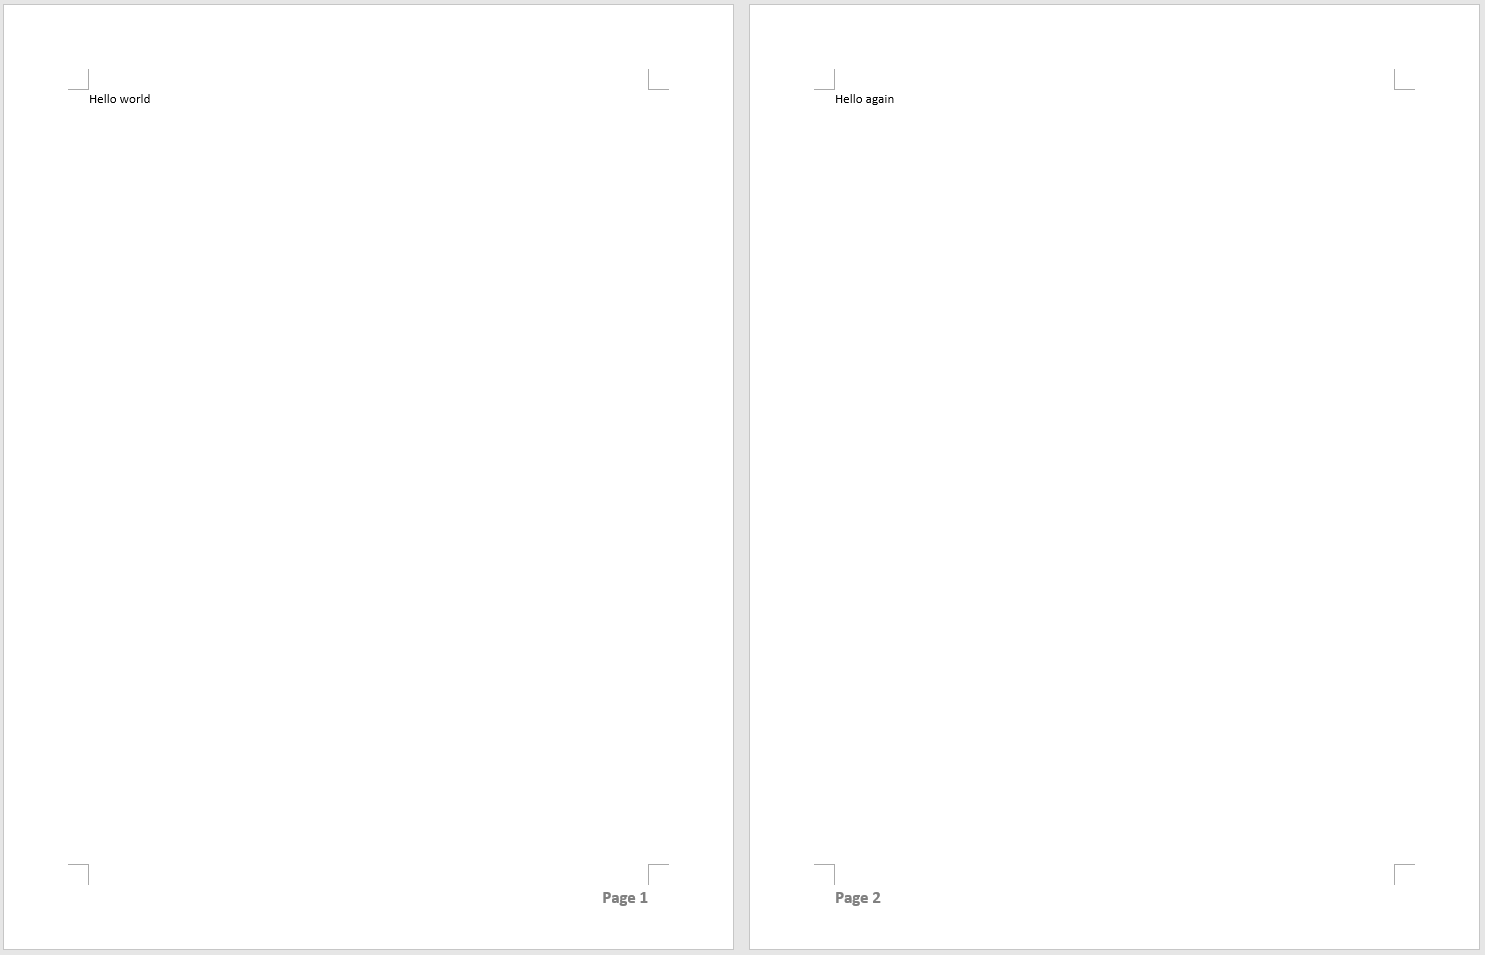

## Create a Template

Create a Word template, `myWordTemplate.dotx`, in the current working directory. Open the file in Word. A reference template that already includes the footers for the example is available in `exampleTemplate.dotx`.

mlreportgen.dom.Document.createTemplate("myWordTemplate","docx");

## Add a Footer and Page Number

In Word, edit the template footer by double-clicking the footer area. This opens a **Header and Footer Tools Design** tab and moves the cursor into the footer area. Type what should appear before the page number in the footer. In the following example, "Page " precedes the page number:

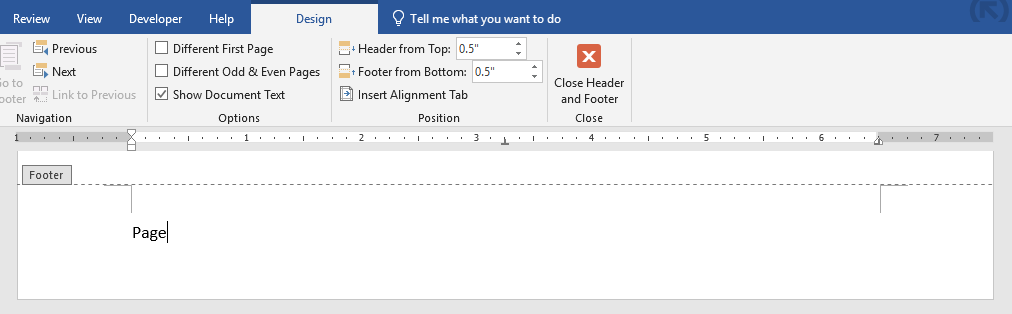

In the **Header and Footer Tools Design** tab open the **Page Number** menu and select **Plain Number** from the **Current Position** options. This will insert a page number at the current position of the cursor.

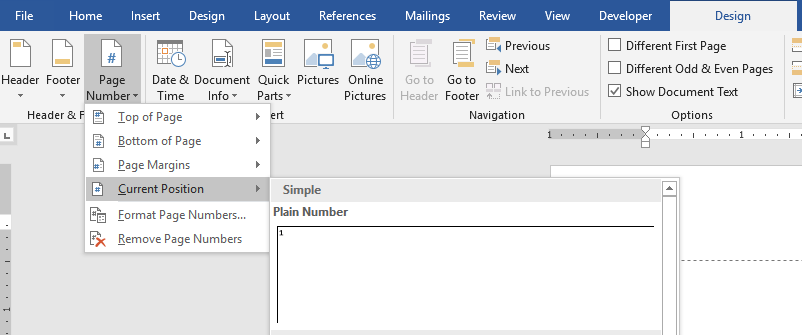

Open the **Page Number** menu again and select **Format Page Numbers... **In the **Page Number Format** menu, set the starting number to 1 and select **OK**.

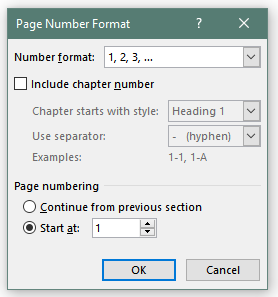

Format the footer text as you would format any text within Word. In this example, the font size is set to 14 and the text style is bold. Set the horizontal alignment of the text to be right-aligned.

## Create a Different Even Page Footer

To specify a different page footer for even and odd pages, select the **Different Odd & Even Pages** option in the **Header and Footer Tools Design** tab.

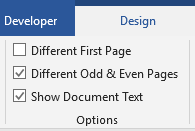

To view the even page footer, add another page to the document. Double-click in the body section of the document or click **Close Header and Footer** to edit the main body of the document. Insert a page break by clicking the **Page Break** button in the **Insert** tab or by pressing **CTRL + Enter**. 

Double-click the footer area in the new page to edit the even page footer. Repeat the earlier process to add text and a page number to the even page footer. Leave the horizontal alignment of the text as the default left-aligned. There is no need to modify the starting number in the **Page Number Format** menu because the page number is automatically increased from the previous page.

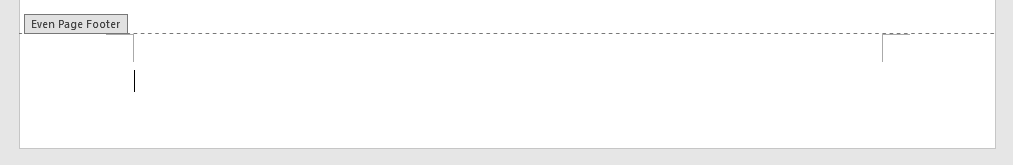

Return to editing the main body of the document. Delete the second page of the document and save the template.

## Use the Template

Use the template by specifying the template name when creating the document. The following code uses the reference template `exampleTemplate.dotx` to create a document. To use the template modified by the example, replace `exampleTemplate` with `myWordTemplate`.

import mlreportgen.dom.*

d = Document("myDocument", "docx", "exampleTemplate");
open(d);

append(d, "Hello world");
append(d, PageBreak());
append(d, "Hello again");
append(d, PageBreak());
append(d, "Hello again");
append(d, PageBreak());
append(d, "Hello again");
append(d, PageBreak());
append(d, "Hello again");

close(d);
rptview(d);

*Copyright 2019 The MathWorks, Inc.*